# **Basics**

**This example shows how you can read MoCap files into Matlab and edit and visualize the data as time series**

**The .mat file 'mcdemodata.mat' contains some motion capture data and associated parameter files.**

addpath(genpath('~/Documents/MATLAB/mocaptoolbox')) % add MoCap Toolbox to path so Matlab can find it. Please adapt this to your needs
load mcdemodata
whos

**Variable walk1 is a mocap structure:**


walk1

**Let us look if there are any missing data in the variable walk1:**


mcmissing(walk1,plot=true);

**Markers 2 and 6 have missing frames. **

**The missing data can be filled using the mcfillgaps function:**


walk1 = mcfillgaps(walk1,100); % only fill gaps whose length is 100 frames or less

[mf, mm, mgrid] = mcmissing(walk1,plot=true);

**The variable walk1 has no more missing frames.**

**Marker location data can be plotted as a function of time using the mcplottimeseries function:**

**for example, plotting marker 3, dimension 3:**


mcplottimeseries(walk1, 3, 'dim', 3) 

**Extracting a temporal part of the data **

w_trim = mctrim(walk1, 2, 4);
mcplottimeseries(w_trim, {'Head_BR','Sternum','Hip_BR'}, 'dim', 1:3)

**Extracting a subset of markers**

w_marker = mcgetmarker(walk1, {'Head_BR','Sternum','Hip_BR'});
mcplottimeseries(w_marker, 1:3, 'dim', 3); 

# **Visualizing MoCap frames**

**This example shows how you can visualize MoCap frames**

**Let's load the demo data**


clear
load mcdemodata

**Marker locations in single frames can be plotted using the mcplotframe command (this command plots the (x,z) projection of the markers):**


mcplotframe(walk1, 160); % plots frame 160

**This uses the default settings for the animation parameters:**


mcinitanimpar

**To get a visualisation that is easier to understand, the markers should be connected. **

**The variable mapar ... **


mapar

**... contains a connection matrix that is suitable for walk1:**


mapar.conn'

**It also has a smaller screensize than the default:**


mapar.scrsize

**Using the mapar variable, we get the following visualization:**


mcplotframe(walk1, 160, mapar);

**It is possible to plot multiple frames in the same figure:**

close % close previous figure
mapar.hold=1;
mcplotframe(walk1,[1 120],mapar);
mapar.hold=0;


**We can add marker numbers to a plot by setting:**


mapar.showmnum = 1;
mcplotframe(walk1, 160, mapar);

**Different colors can be used:**


mapar.colors='wbgcr';
mcplotframe(walk1, 160, mapar);

**Or like this**


mapar.markercolors='bwwgwrwwwwwywwwwwwmwcbwg';
mcplotframe(walk1, 160, mapar);

**And the connector widths and marker sizes can be adjusted:**


mapar.msize=6; 
mapar.cwidth = 3;
mcplotframe(walk1, 160, mapar);


**The viewing azimuth and elevation can be changed:**


mapar.az = 45;
mapar.el = 20;
mcplotframe(walk1, 160, mapar);

**To add even more color, a background image can also be set:**

mapar.background.input = 'peppers.png';
mapar.background.fillfigure=1;
mcplotframe(walk1, 160, mapar);

# **Animations**

**This example shows how you can create animations with the MoCap toolbox. **

**You can either produce an animation video (.avi or .mp4 format), an animated .gif file, or animation frames (single .png files) with the MoCap toolbox. In this tutorial we will produce an .mpg4 file.**

**Let us create an animation from the variable walk2. We first load the mocap demo data and the path/folder to store the animation file**

clear
load mcdemodata


**The animpar structure mapar contains the connector information for this variable: Let us change the animation frame rate (in frames per second) value to 10, change the output format to mpeg4 and name the file:**


mapar.fps = 10;
mapar.videoformat = 'mpeg4'; 
mapar.output = 'video1';


**Now we make the animation, which is produced by default in the current working directory. **

mcanimate(walk2, mapar);


**The next example shows how MoCap data from different sessions can be combined into the same animation. It also shows how the viewing angle can be changed dynamically. Let us create a 5-second animation with two dancers and a dynamically moving viewing angle:**


dance1 = mcfillgaps(dance1); % fill gaps
d1 = mctrim(dance1, 0, 5); % take first 5 seconds (dancer 1)
d2 = mctrim(dance2, 0, 5); % same for dancer 2
mapar.az = [0 180]; % azimuth changes from 0 to 180 degrees during the animation
mapar.el = [45 -45]; % elevation changes from 45 to -45 degrees
mapar.output = 'twodancers';
mapar.videoformat = 'mpeg4'; 
dt = mctranslate(d2, [2000 0 0]); % translate d2 over the x axis by 2000 mm 
[d, par] = mcmerge(d1, dt, mapar, mapar);

mcanimate(d, par);


**Let us set some individual colors for six markers (head front left, head back right, shoulder left, hip left back, finger right, knee left, knee right, heel left) and add colored traces to these markers:**


mapar.markercolors='bwwgwrwwwwwywwwwwwmwcbwg';
mapar.trm=[1 6 12 19 21 24]; %trace markers
mapar.trl=3; %trace length
mapar.tracecolors='grymcb'; %trace colors
mapar.output='traces1';
mapar.az=0; %reset previous changes
mapar.el=0;

mcanimate(walk2, mapar);


**Let's explore how to create animations with a perspective (three-dimensional) effect.  **

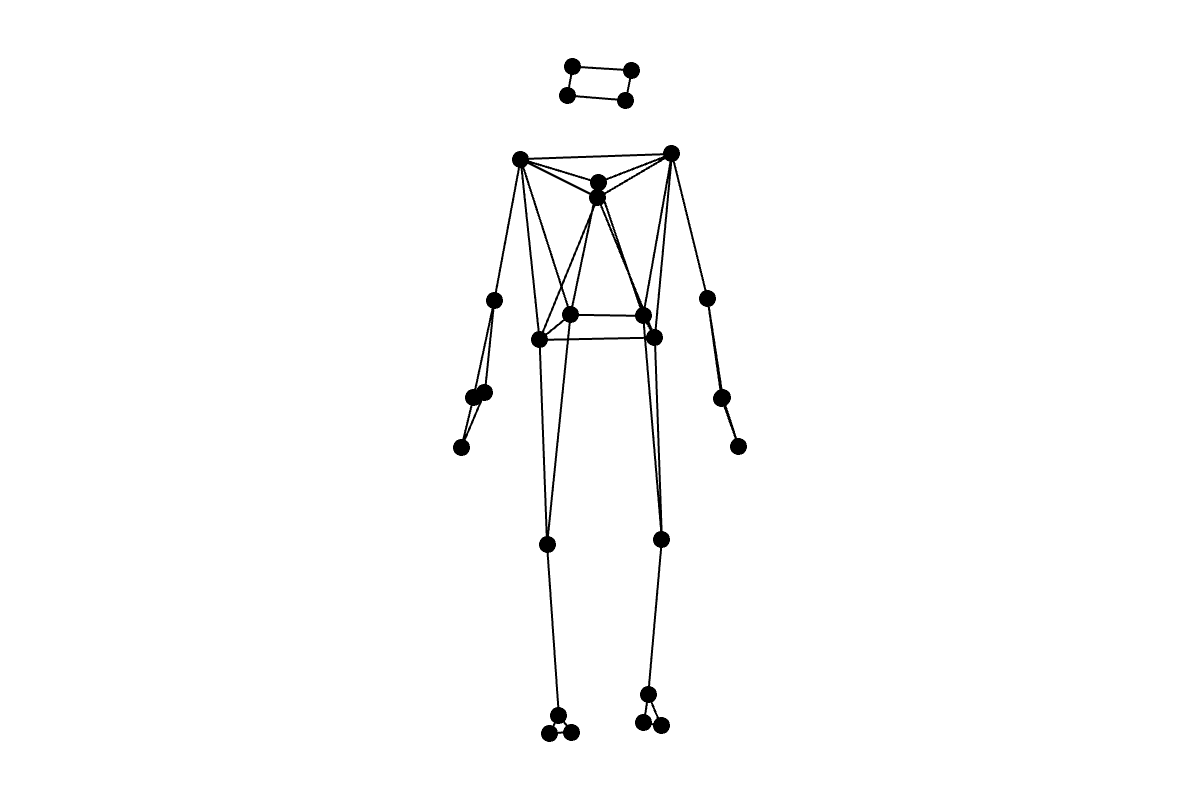

mapar.trl=0;
mapar.scrsize=[600 400];
mapar.az=270; %so that the walker walks towards us
mapar.msize=8;
mapar.colors='wkkkk'; %reset colors
mapar.markercolors='';
mapar.output = 'pers0';
mcplotframe(walk2,100,mapar); % preview the result

**Create an animation without the perspective projection**


mcanimate(walk2, mapar); 


**Create an animation with the perspective projection**


mapar.output = 'pers1';
mapar.perspective = 1;

mcanimate(walk2, mapar);


**The parameters for the perspective projection are set in the pers part of the animpar structure mapar**


mapar.pers


**The field c sets the 3D position of the camera, th is the orientation of the camera, and e stores the viewer's position relative to the display surface. We can now change, for example, the camera position and create another animation to see what happens.**


mapar.output = 'pers2';

mapar.pers.c=[1000 -4000 1000];

mcanimate(walk2, mapar);

# **Representations and transformation**

**This example summarises data coordinate representations and transformations, which are useful e.g. for distinguishing mediolateral and anteroposterior movements.**

**Let's have a look at different possibilities to change the representation of the data.**

***mccenter***** centers the data at [0 0 0]:**

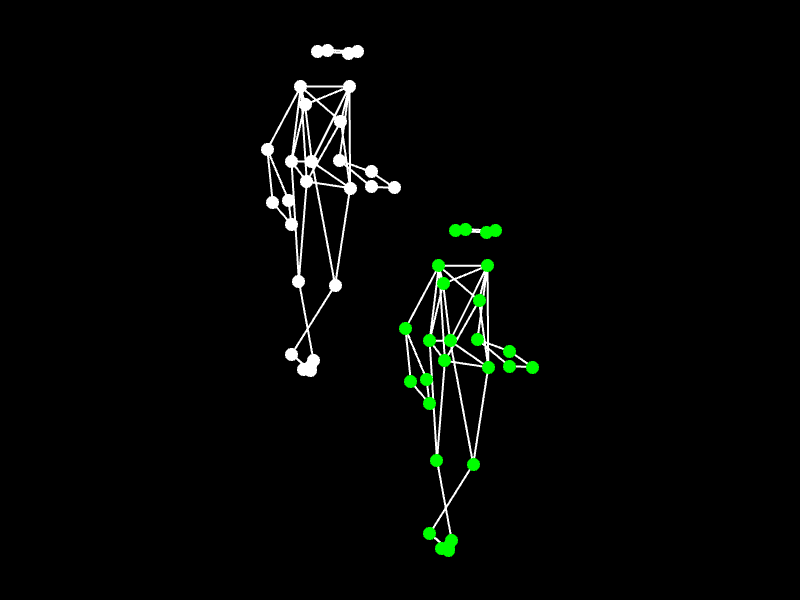


clear 
load mcdemodata
d=mctrim(dance2,0,4);

dc=mccenter(d);
mapar1=mapar;
mapar1.colors='kgwww';
[dd, mapar2]=mcmerge(d,mctranslate(dc,[1000 0 0]),mapar,mapar1);
mcplotframe(dd,200,mapar2);

***mcrotate***** rotates the data with a given angle**

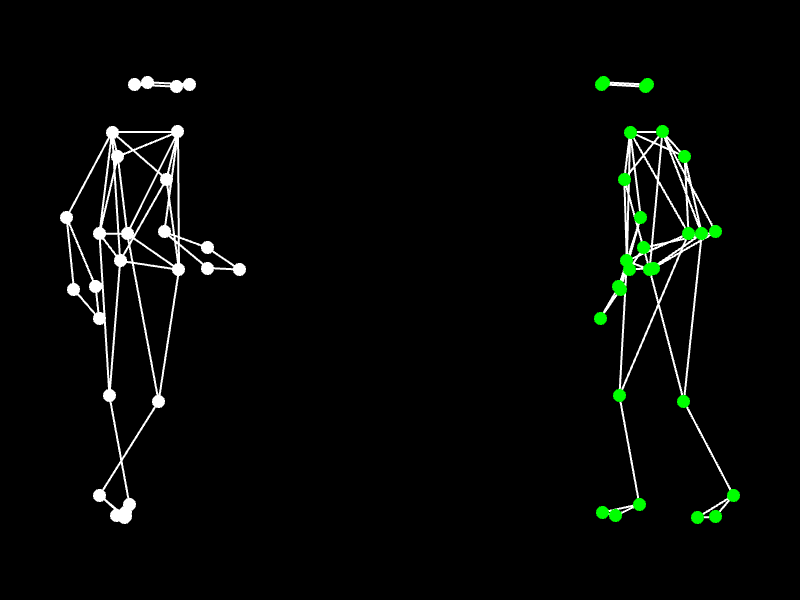


dr=mcrotate(d,110); % rotates by default around the vertical axis
[dd, mapar2]=mcmerge(d,mctranslate(dr,[1000 0 0]),mapar,mapar1);
mcplotframe(dd,200,mapar2);

***mc2frontal *****rotates the data to have a frontal view on average (default) or for each frame ('frame')**

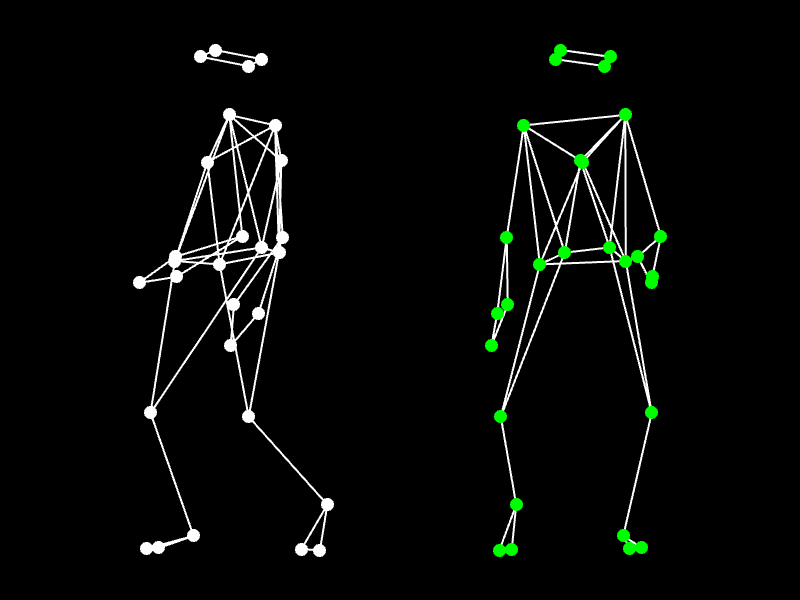


df=mc2frontal(d, 11, 12,'frame'); %back hips define the frontal plane
mapar1=mapar;
mapar1.colors='kgwww';
[dd, mapar2]=mcmerge(d,mctranslate(df,[1000 0 0]),mapar,mapar1);
mcplotframe(dd,100,mapar2);

**Coordinate transformation from global to local (e.g., expressed relative to the body) system**

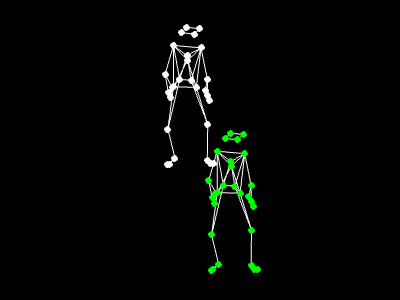


d2=mc2local(d,8,[11,12]); % sternum as origin, frontal view for each frame based on front hip markers 
mapar1=mapar;
mapar1.colors='kgwww';
[dd, mapar2]=mcmerge(mc2frontal(d, 11, 12),mctranslate(d2,[1000 0 0]),mapar,mapar1);
mapar2.fps = 15;
mapar2.videoformat = 'mpeg4'; 
mapar2.output = 'local2';
mcanimate(dd, mapar2);

# **Time derivatives and statistics**

**This example shows how you can estimate kinematic variables from MoCap data and visualize them.**

**Time derivatives of motion-capture data can be estimated using the mctimeder function:**


clear
load mcdemodata
d2v = mctimeder(dance2, 1); %velocity
d2a = mctimeder(dance2, 2); %acceleration

**In order to compare, let's have a look at the vertical position, velocity and accleration of markers 1, 19, and 25 (head, hand, and foot). First, we plot the position components:**

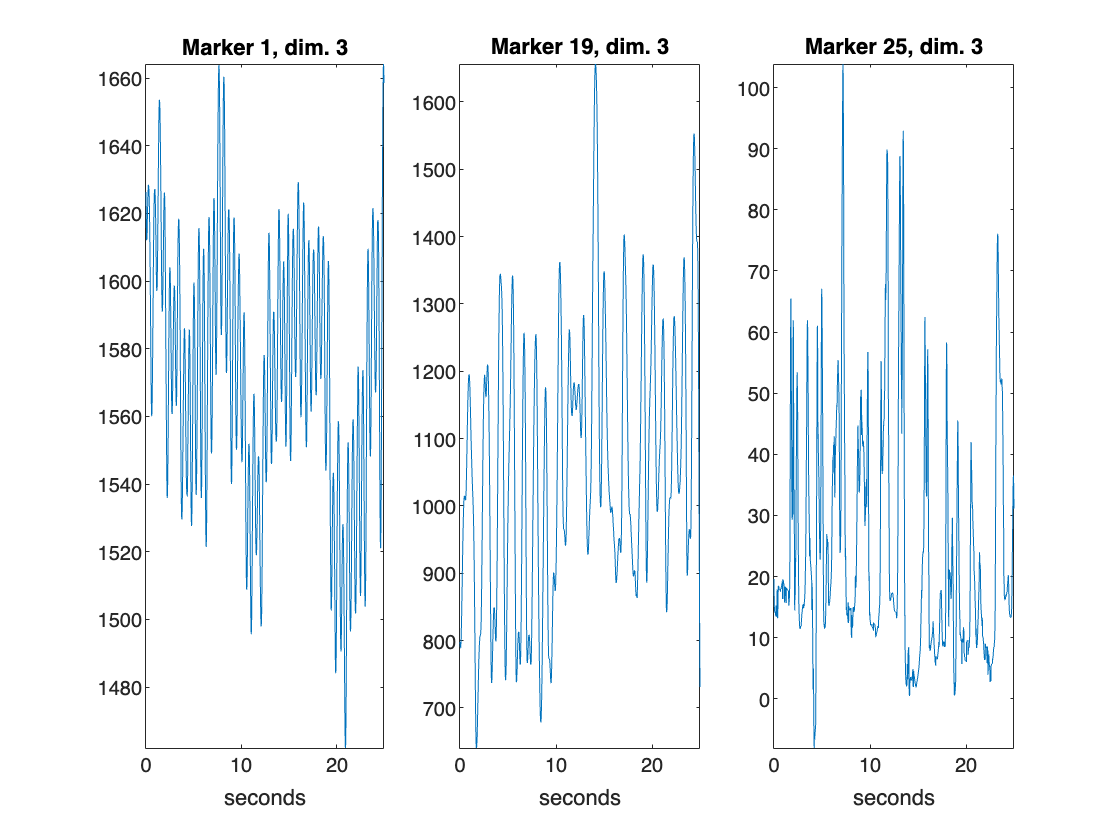

mcplottimeseries(dance2, [1 19 25], 'dim', 3)

**Then the vertical velocity components:**

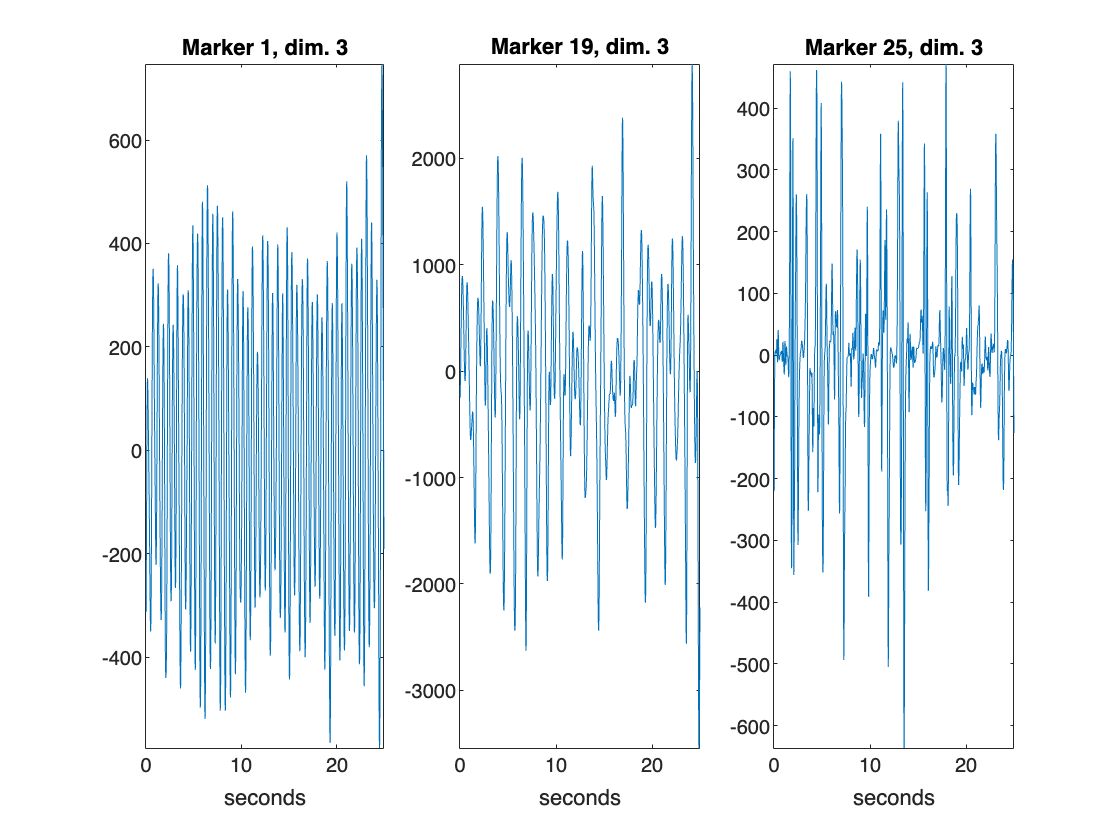


mcplottimeseries(d2v, [1 19 25], 'dim', 3)

**And finally the vertical acceleration components of the same markers**

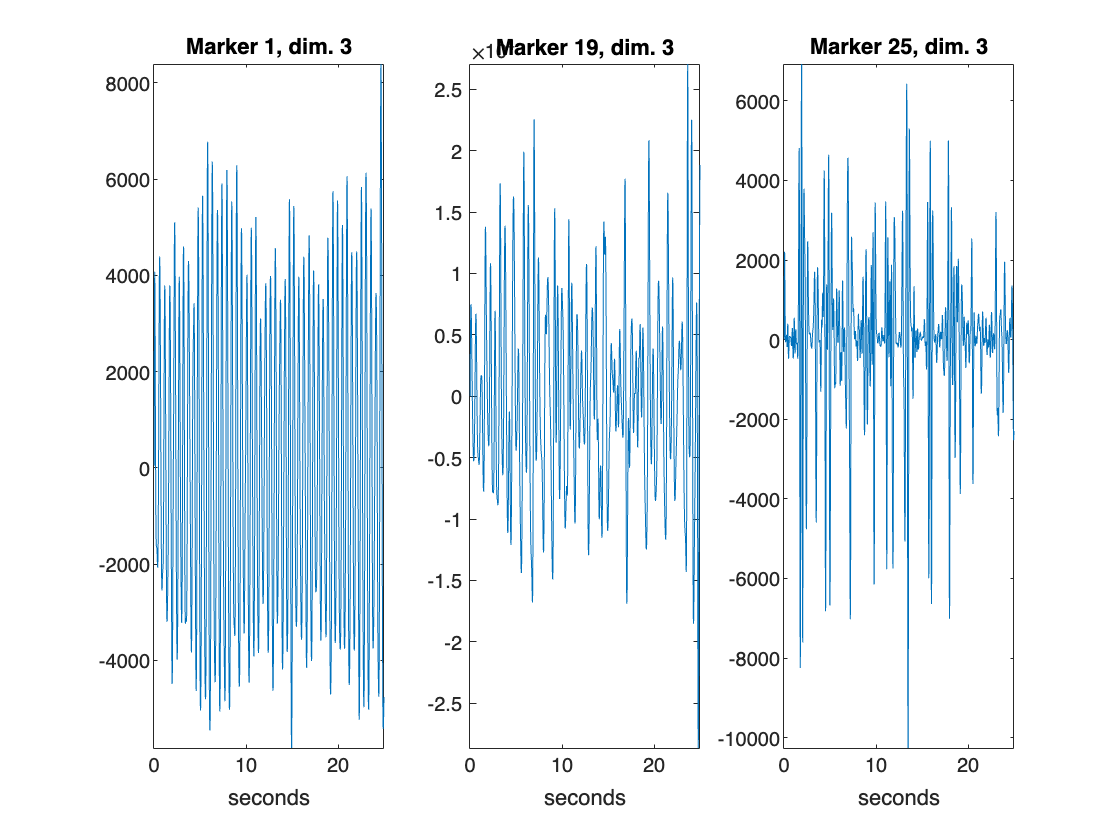


mcplottimeseries(d2a, [1 19 25], 'dim', 3)

**We can do statistical analyses on the time-series data using the functions provided in the MoCap toolbox**

**The first statistical moments, mean, standard deviation, skewness, and kurtosis, can be calculated using the functions mcmean, mcstd, mcskewness, and mckurtosis, respectively. These functions ignore any missing frames.**

**Let us calculate the standard deviations for the markers 1, 19, and 25 (head, hand, and foot) in the Mocap structure dance1:**


std1 = mcstd(mcgetmarker(dance1, [1 19 25]))

std1 =   141.6964  238.3940   39.2675  139.1145  185.0342   38.8289  157.5374  173.4826    5.8142


std(dance1.data)

**Windowed analysis of the statistical time-series descriptors can be carried out using the mcwindow command.**

**Let us compute the windowed standard deviation (window length of 2, hop factor of 0.5) of markers 1, 19, and 25 (head, hand, and foot) in the Mocap structure dance1:**


marker = [1 19 25];
d1std=mcwindow(@mcstd, mcgetmarker(dance1, marker), 2, 0.5)

d1std =    53.4994   27.7538   15.1347   52.4284   30.3001   16.4769   93.4508   53.0240    7.5579
   33.0890   67.1181   15.4266   42.3624   85.2826   19.0369  149.5238   94.4498    8.0354
   15.5863   37.2955   13.8447   37.4789   61.0072   23.1599    1.4534    1.4371    1.5517
   52.3360   32.6450   13.2071   90.4688   45.3428   33.8297    1.8959    1.0586    0.5140
   36.5909   29.7810   17.3000   70.6230   16.8939   29.3611   20.1300   16.5444    5.5579
   78.0532  102.3693   45.8472  107.8113   28.0383   31.2492   37.5741   88.2017    9.9737
   46.0928   76.8372   25.0567   36.5913   36.8718   40.2661    3.9424    9.6590    8.6936
   46.4126   51.6767   26.5749   21.1753   30.9685   33.1108    4.1602    7.8956    2.7795
   64.7753    8.2124   41.8290   22.5371   23.7610   40.5907    3.3575   11.2123    4.0688
   76.6089   27.4579   14.6652   74.5127   27.8328   28.1224   15.0708   13.5977    2.6365


# **Joint and segment representation**

**This example shows how the toolbox can be used to create joint and segment representations and calculate kinetic variables (i.e., energy) from MoCap data using Dempster's body-segment model.**

**Let us first plot a MoCap frame with marker numbers:**

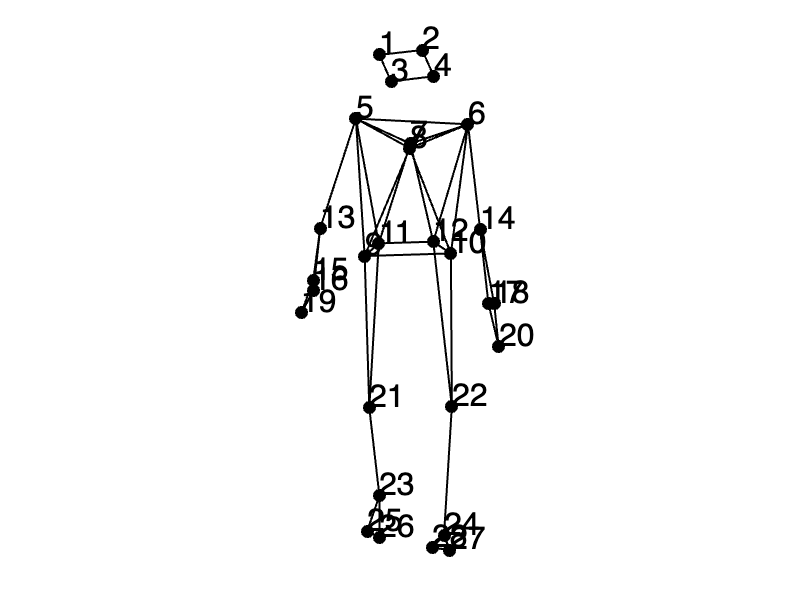

clear
load mcdemodata
mapar.colors = 'wkkkk';
mapar.showmnum = 1;
mapar.msize=6;
mapar.az=90;
mcplotframe(walk2,160, mapar);

**The first thing to do is to reduce the set of markers to make the data compatible with Dempster's model. This can be accomplished using the marker-to-joint transformation. The parameters needed for this conversion are in the variable m2jpar:**

m2jpar = struct with fields:
          type: 'm2jpar'
      nMarkers: 20
     markerNum: {[9 10 11 12]  [9 11]  [21]  [23]  [25 26]  [10 12]  [22]  [24]  [27 28]  [7 8 7 8 9 10 11 12]  [5 6]  [1 2 3 4]  [5]  [13]  [15 16]  [19]  [6]  [14]  [17 18]  [20]}
    markerName: {'root'  'lhip'  'lknee'  'lankle'  'ltoe'  'rhip'  'rknee'  'rankle'  'rtoe'  'midtorso'  'neck'  'head'  'lshoulder'  'lelbow'  'lwrist'  'lfinger'  'rshoulder'  'relbow'  'rwrist'  'rfinger'}


**The information about which markers correspond to each joint is in the field m2jpar.markerNum. The names of the new joints are in m2jpar.markerName. For instance, ...**


m2jpar.markerName{1}

ans = 'root'

m2jpar.markerNum{1}

ans =      9    10    11    12


**... the joint 'root' is obtained by calculating the centroid of markers 9, 10, 11 and 12**

**The marker-to-joint conversion is carried out like this:**


walk2j = mcm2j(walk2, m2jpar)

walk2j = struct with fields:
            type: 'MoCap data'
        filename: '25-Walking.tsv'
         nFrames: 401
        nCameras: 8
        nMarkers: 20
            freq: 60
         nAnalog: 0
         anaFreq: 0
    timederOrder: 0
      markerName: {'root'  'lhip'  'lknee'  'lankle'  'ltoe'  'rhip'  'rknee'  'rankle'  'rtoe'  'midtorso'  'neck'  'head'  'lshoulder'  'lelbow'  'lwrist'  'lfinger'  'rshoulder'  'relbow'  'rwrist'  'rfinger'}
            data: [401x60 double]
      analogdata: []
           other: [1x1 struct]


**The parameters for the visualization of the joint representation are in the variable japar:**


japar

japar = struct with fields:
            type: 'animpar'
         scrsize: [400 300]
          limits: []
              az: 0
              el: 0
           msize: 6
          colors: 'kwwww'
    markercolors: []
      conncolors: []
     tracecolors: []
    numbercolors: []
          cwidth: 1
          twidth: 1
            conn: [19x2 double]
           conn2: []
             trm: []
             trl: 0
        showmnum: 0
         numbers: []
        showfnum: 0
      background: [1x1 struct]
         animate: 0
         visible: 1
            hold: 0
             fps: 30
          output: 'tmp'
     videoformat: 'avi'
    createframes: 0
       getparams: 0
     perspective: 0
            pers: [1x1 struct]


**Let us visualize a frame from the new variable with marker numbers:**

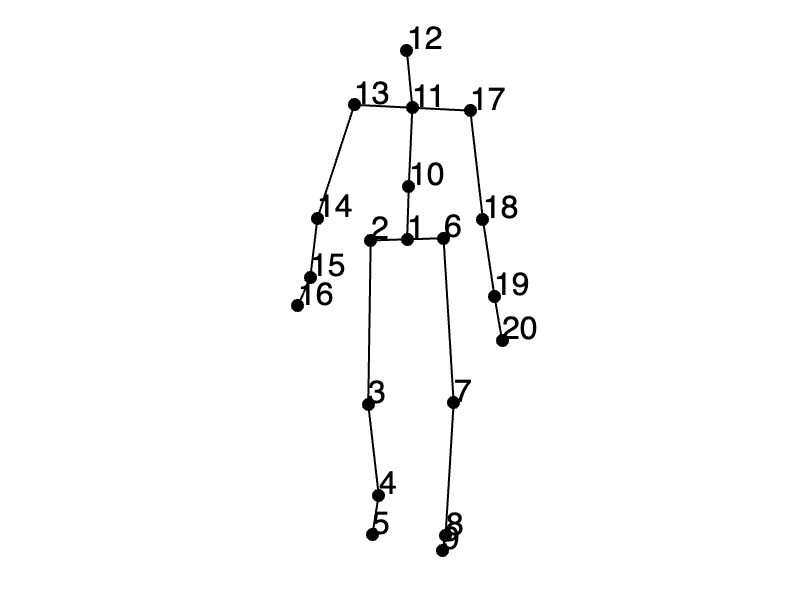


japar.colors = 'wkkkk';
japar.showmnum = 1;
japar.msize=6;
japar.az=90;
mcplotframe(walk2j,160, japar);

**The next step is to make a joint-to-segment transformation. The parameters needed for this are in the variable j2spar.**


j2spar

j2spar = struct with fields:
            type: 'j2spar'
      rootMarker: 1
    frontalPlane: [6 2 10]
          parent: [0 1 2 3 4 1 6 7 8 1 10 11 11 13 14 15 11 17 18 19]
     segmentName: {'lhip'  'lthigh'  'lleg'  'lfoot'  'rhip'  'rthigh'  'rleg'  'rfoot'  'ltorso'  'utorso'  'neck'  'lshoulder'  'luarm'  'llarm'  'lhand'  'rshoulder'  'ruarm'  'rlarm'  'rhand'}


**The transformation can be accomplished using the function mcj2s. **


walk2s = mcj2s(walk2j, j2spar)

walk2s = struct with fields:
            type: 'segm data'
        filename: '25-Walking.tsv'
         nFrames: 401
        nCameras: 8
        nMarkers: 20
            freq: 60
         nAnalog: 0
         anaFreq: 0
    timederOrder: 0
      analogdata: []
           other: [1x1 struct]
          parent: [0 1 2 3 4 1 6 7 8 1 10 11 11 13 14 15 11 17 18 19]
       roottrans: [401x3 double]
         rootrot: [1x1 struct]
            segm: [1x20 struct]
     segmentName: {'lhip'  'lthigh'  'lleg'  'lfoot'  'rhip'  'rthigh'  'rleg'  'rfoot'  'ltorso'  'utorso'  'neck'  'lshoulder'  'luarm'  'llarm'  'lhand'  'rshoulder'  'ruarm'  'rlarm'  'rhand'}


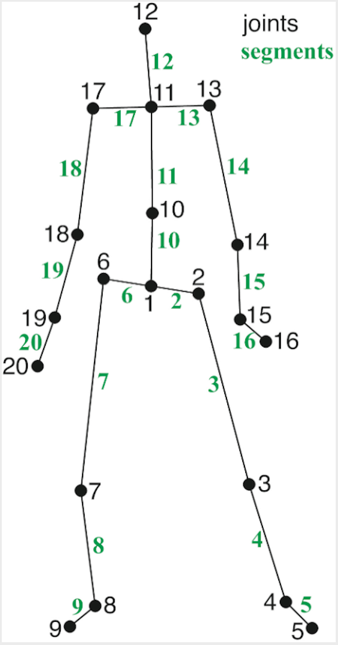

**This figure illustrates the relationship between joints and segments.**

**Let's check out walk2s in the variable viewer window.**

**The parameters (e.g. mass relative to total body mass) for each body segment can be obtained using the function mcgetsegmpar:**


spar = mcgetsegmpar('Dempster',[0 0 8 7 6 0 8 7 6 13 12 10 11 3 2 1 11 3 2 1])

spar = struct with fields:
       type: 'segmpar'
          m: [0 0 0.1000 0.0465 0.0145 0 0.1000 0.0465 0.0145 0.1390 0.2160 0.0810 0.0158 0.0280 0.0160 0.0060 0.0158 0.0280 0.0160 0.0060]
    comprox: [0 0 0.4330 0.4330 0.5000 0 0.4330 0.4330 0.5000 0.4400 0.8200 1 0.7120 0.4360 0.4300 0.5060 0.7120 0.4360 0.4300 0.5060]
    comdist: [0 0 0.5670 0.5670 0.5000 0 0.5670 0.5670 0.5000 0.5600 0.1800 0 0.2880 0.5640 0.5700 0.4940 0.2880 0.5640 0.5700 0.4940]
      rogcg: [0 0 0.3230 0.3020 0.4750 0 0.3230 0.3020 0.4750 0 0 0.4950 0 0.3220 0.3030 0.2980 0 0.3220 0.3030 0.2980]
    rogprox: [0 0 0.5400 0.5280 0.6900 0 0.5400 0.5280 0.6900 0 0 1.1160 0 0.5420 0.5260 0.5870 0 0.5420 0.5260 0.5870]
    rogdist: [0 0 0.6530 0.6430 0.6900 0 0.6530 0.6430 0.6900 0 0 0.4950 0 0.6450 0.6470 0.5770 0 0.6450 0.6470 0.5770]


**The second argument in the function call associates each joint in walk2j and walk2s with a segment type. The numbers refer to the distal joint of the respective segment. Joints that are not distal to any segment have zero values. Segment number values for model 'Dempster' are as follows: no parameter=0, hand=1, forearm=2, upper arm=3, forearm and hand=4, upper extremity=5, foot=6, leg=7, thigh=8, lower extremity=9, head=10, shoulder=11, thorax=12, abdomen=13, pelvis=14, thorax and abdomen=15, abdomen and pelvis=16, trunk=17, head, arms and trunk (to glenohumeral joint)=18, head, arms and trunk (to mid-rib)=19.**

**For instance, the third component, 8, tells that the body segment whose distal joint is joint number 3, is a 'thigh'.**

**The instantaneous potential energy for each body segment can now be calculated as follows:**


pot = mcpotenergy(walk2j, walk2s, spar)

pot =          0         0   61.1498   12.6394    0.5386         0   60.6924   13.4037    0.3405   84.7065  154.0943   70.2964   13.7106   24.2531   10.2300    3.0153   13.7106   24.3360   10.5868    3.0859
         0         0   61.2310   12.6871    0.5793         0   60.8163   13.4079    0.3366   84.8491  154.3462   70.4468   13.7399   24.3193   10.2634    3.0132   13.7399   24.3738   10.6173    3.0984
         0         0   61.3198   12.7993    0.6222         0   60.9660   13.4141    0.3332   85.0148  154.6035   70.5392   13.7579   24.3473   10.2933    3.0133   13.7580   24.4097   10.6493    3.1112
         0         0   61.4668   12.8636    0.6443         0   61.0887   13.2663    0.3303   85.2024  154.8603   70.6271   13.7751   24.3743   10.3247    3.0227   13.7751   24.4435   10.6790    3.1247
         0         0   61.5471   12.9214    0.6745         0   61.1893   13.2792    0.3264   85.3281  155.0562   70.7055   13.7904   24.3991   10.3521    3.0282   13.7904   24.4729   10.7072

**This is a matrix where each column corresponds to a body segment.**

**The total potential energy can be plotted as follows:**


figure
set(gcf,'Position',[40 450 400 300])
plot((1:walk2.nFrames)/walk2.freq, sum(pot,2))
xlabel('Time / s')
ylabel('Potential energy / W')

**The instantaneous translational and rotational energy for each body segment can be calculated as follows:**


[trans, rot] = mckinenergy(walk2j, walk2s, spar)

trans =          0         0    0.6465    0.3319    0.0193         0    0.9696    0.0634    0.0006    1.3031    2.1215    0.4937    0.0773    0.1931    0.2033    0.2857    0.3404    1.0227    0.8199    0.3482
         0         0    0.6465    0.3319    0.0193         0    0.9696    0.0634    0.0006    1.3031    2.1215    0.4937    0.0773    0.1931    0.2033    0.2857    0.3404    1.0227    0.8199    0.3482
         0         0    0.6386    0.3558    0.0212         0    0.9164    0.0498    0.0007    1.3060    2.0399    0.4609    0.0716    0.1753    0.2263    0.2461    0.3202    0.9652    0.7953    0.3493
         0         0    0.6407    0.3931    0.0265         0    0.8817    0.0419    0.0008    1.2958    1.9525    0.4230    0.0681    0.1618    0.2469    0.2144    0.3010    0.9111    0.7706    0.3490
         0         0    0.6497    0.4415    0.0347         0    0.8660    0.0411    0.0008    1.2611    1.8488    0.3820    0.0648    0.1524    0.2614    0.1894    0.2829    0.8600    0.74

rot =          0         0    0.0297    0.0382    0.0592         0    0.0739    0.0103    0.0010         0         0    0.0104         0    0.0164    0.0301    0.0083         0    0.0136    0.0009    0.0002
         0         0    0.0297    0.0382    0.0592         0    0.0739    0.0103    0.0010         0         0    0.0104         0    0.0164    0.0301    0.0083         0    0.0136    0.0009    0.0002
         0         0    0.0118    0.0243    0.0631         0    0.0811    0.0082    0.0009         0         0    0.0099         0    0.0226    0.0218    0.0052         0    0.0138    0.0011    0.0003
         0         0    0.0035    0.0165    0.0674         0    0.0823    0.0069    0.0008         0         0    0.0107         0    0.0292    0.0156    0.0030         0    0.0139    0.0013    0.0004
         0         0    0.0014    0.0132    0.0706         0    0.0754    0.0066    0.0008         0         0    0.0120         0    0.0347    0.0111    0.0016         0    0.0137    0.0015

**We can use the function mcanimatedata to jointly animate movement and a time series plot. Let's have a look at the walking movement together with total potential and translational energy:**

% NOTE: MCANIMATEDATA throws an error in MATLAB live scripts. To create the
% plot, you can paste the 'Joint and segment representation' example code
% into another MATLAB session. 

figure
set(gcf,'Position',[40 50 400 300])
plot((1:walk2.nFrames)/walk2.freq, sum(trans,2))
xlabel('Time / s')
ylabel('Translational energy / W')
close all;
japar.showmnum=0;
japar.az=0;
japar.fps = 15;
japar.videoformat = 'mpeg4';
japar.output = 'energy';
mcanimatedata(walk2j,japar,'north',sum(pot,2),'northYLabel',{'Pot. energy / W'},'south',sum(trans,2),'southYLabel',{'Trans. energy / W'},'showYTicks','on')

# **PCA on mocap data**

**Let us now look at performing Principal Components Analysis on mocap data.**

**Let's use PCA to decompose Motion Capture data into components that are orthogonal to each other.**

**Let us extract the first four seconds from the structure dance2**


clear
load mcdemodata
d=mctrim(dance2,0,4);


**and convert it into a joint representation**


j=mcm2j(d, m2jpar);


**Next, we calculate the first three principal component projections of the structure j**


[pc,p]=mcpcaproj(j,1:3);


**and plot the amount of variance contained in these principal components**

p.l

ans =     0.8521
    0.0905
    0.0213
    0.0129
    0.0080
    0.0066
    0.0034
    0.0016
    0.0011
    0.0007


**The first PC contains ca. 85% of the variance, while the next two components contain only 9% and 2%.**

**The obtained PC scores and loadings can be used to create animations showing the most characteristic movement patterns. PCA often distorts the body segment relations, in particular, the lengths of certain body segments vary. Often better results can be obtained by performing the PCA on the segment representation:**


s=mcj2s(j,j2spar); %convert to segment structure
[pcs,ps]=mcpcaproj(s,1:3); %perform PCA
for k=1:3 %convert PC projections back to joint structures
    pcj(k) = mcs2j(pcs(k), j2spar);
end

**We can use MATLAB functions to plot the first three PC projections**

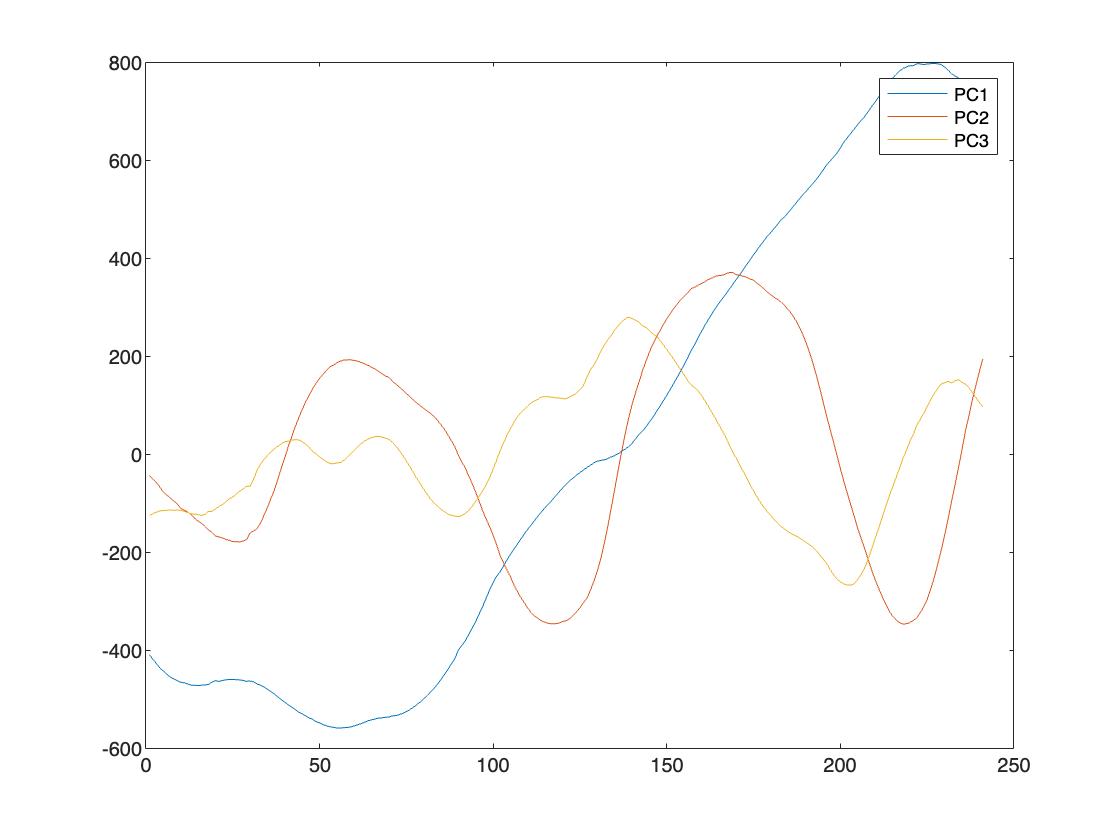


figure, plot(ps.c(1:3,:)'), legend('PC1','PC2','PC3')

**The plot reveals that the first PC correspond to non-periodic motion, while PCs 2 and 3 correspond to (almost) periodic motion. If we animate pcj(1), pcj(2), pcj(3), we will see that the first three PCs correspond to translation of the body, periodic anti-phase movement of arms, and periodic rotation of torso. Let's animate, for instance, the second projection:**


japar.fps = 15;
japar.videoformat = 'mpeg4';
japar.output = 'PC2';
mcanimate(pcj(2),japar);


# **Movement feature extraction**

**Let us now look at calculating different movement features and descriptors.**

**The cumulative distance travelled by a marker can be calculated with the function mccumdist. Let us have a look at the distance travelled by markers 1, 19, and 25 (head, hand, and foot):**

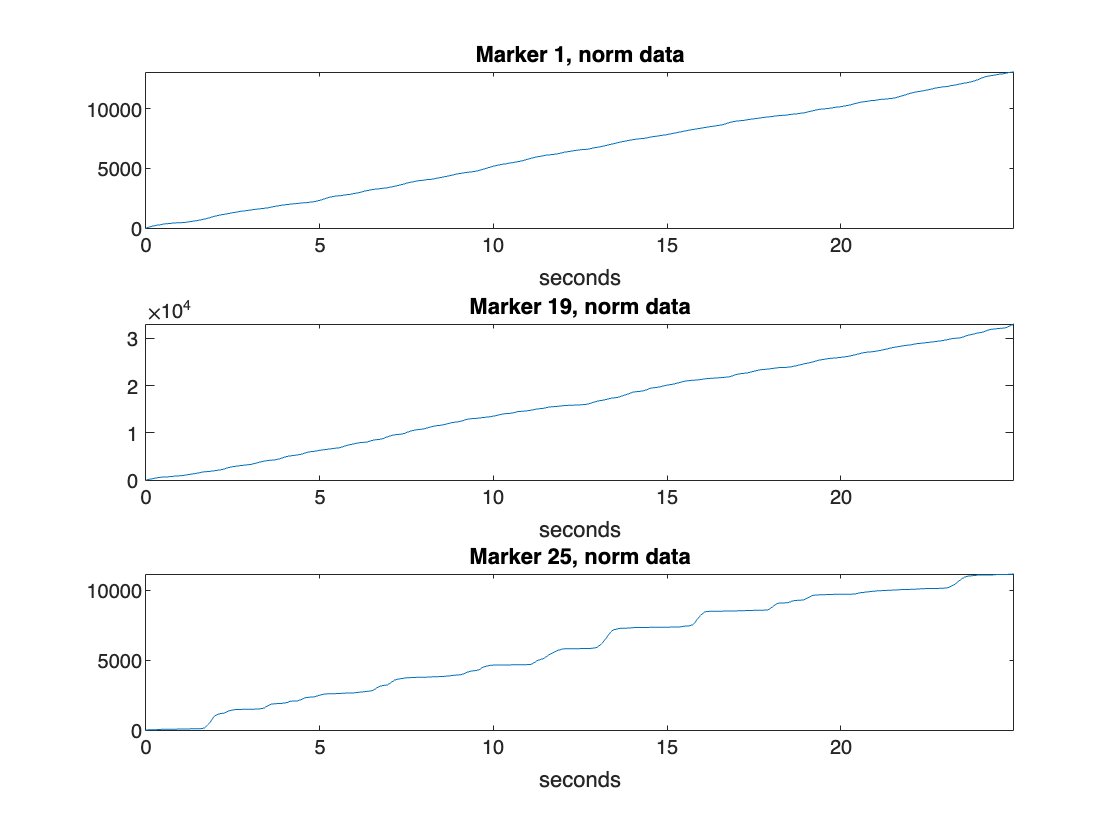


clear
load mcdemodata
d2dist=mccumdist(dance2);
mcplottimeseries(d2dist, [1 19 25])

**As we can see, the head has travelled ca. 13 meters, the hand ca. 33 meters, and the foot ca. 11 meters.**

**Distances between markers can be calculated using mcmarkerdist:**

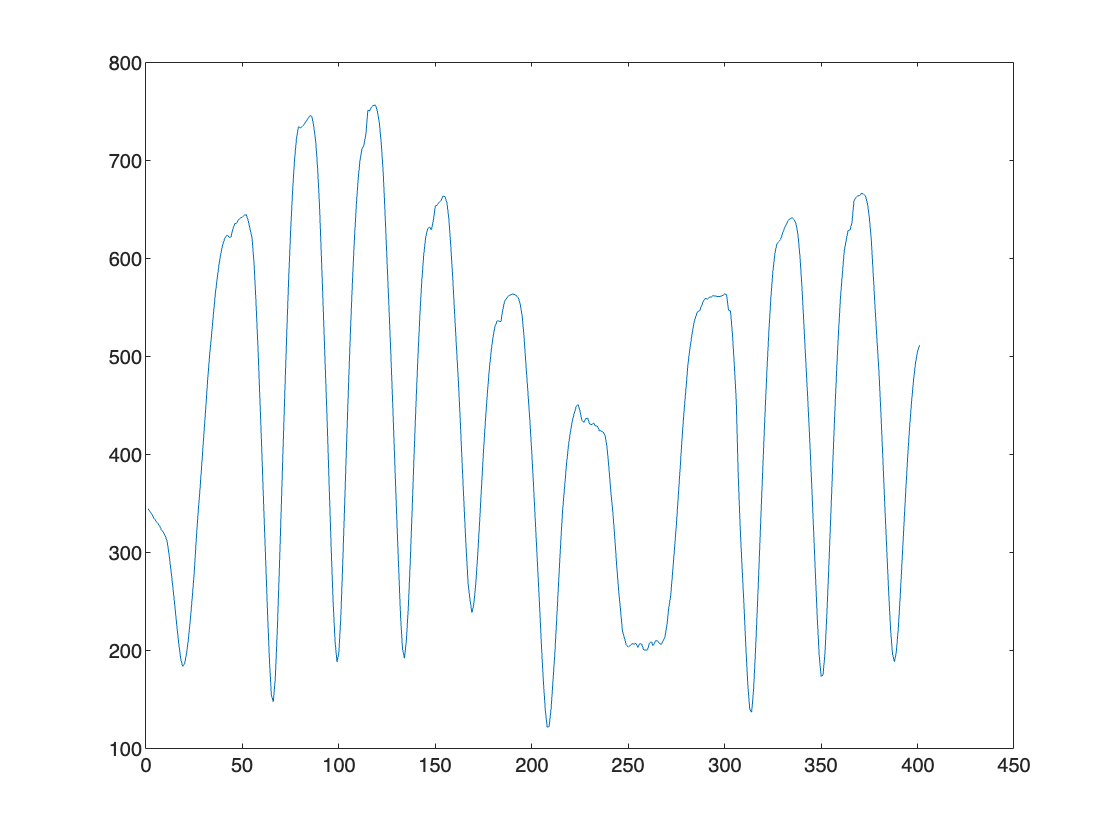


mdist=mcmarkerdist(walk2, 26, 28);
figure, plot(mdist)

**The area covered (i.e., smallest rectangle) in m² within a determined period of time (default is 4 s with 50% overlapping) can be calculated with mcboundrect (calculation is marker-based, so averaging across all markers is not necessarily useful...) **


brw=mean(mcboundrect(walk2,28))

brw = 2.3887

brd=mean(mcboundrect(dance2,28))

brd = 0.3798


brwa=sum(mean(mcboundrect(walk2,1:28)))

brwa = 47.0434

brda=sum(mean(mcboundrect(dance2,1:28)))

brda = 16.0386

**A related feature is mcboundvol, which computes, for each time point, the convex hull volume (or its corresponding area on the horizontal plane) that envelopes the mocap data points.**

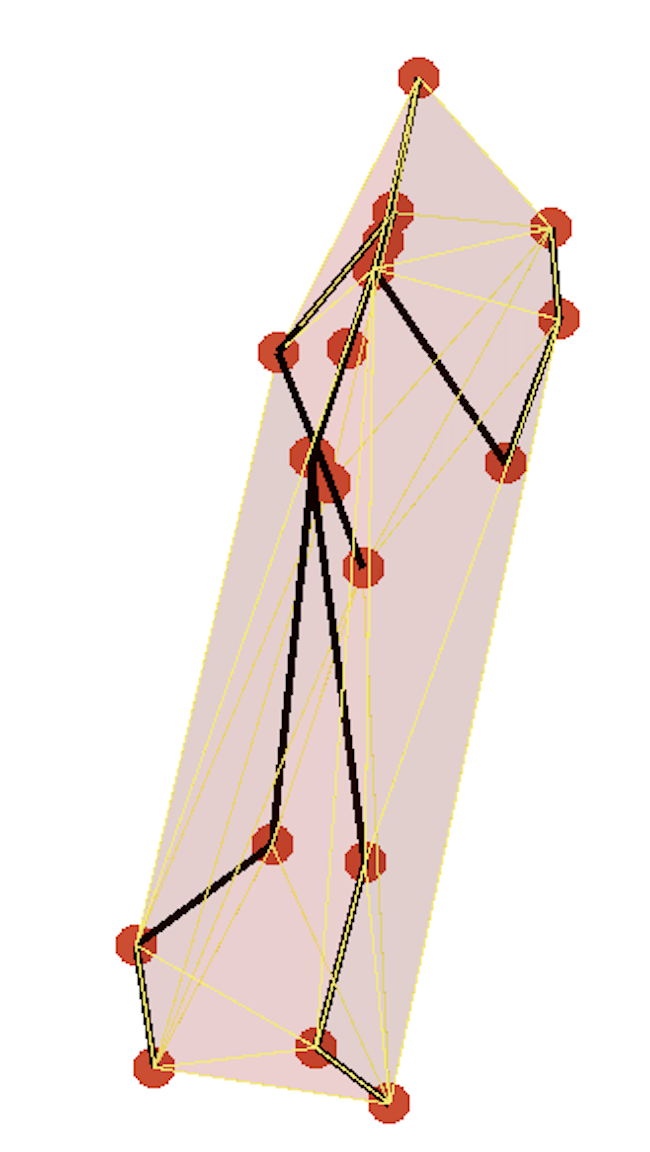

v = mean(mcboundvol(dance2)) % mean volume (in cubic meters) across time
v = mean(mcboundvol(dance2,'type','area'))

**Fluidity or smoothness can be calculated using mcfluidity (ratio between velocity and acceleration of normed and averaged mocap data):**


fw=mcfluidity(walk2, 19)

fw = 0.1802

fd=mcfluidity(dance2, 19)

fd = 0.1371

**Rotation range between two markers can be calculated using mcrotationrange:**


rw=mcrotationrange(walk2, 5, 6)
rd=mcrotationrange(dance2, 5, 6)


**Movement complexity or dimensionality can be calculated using mccomplexity:**


cw=mccomplexity(walk2)
cd=mccomplexity(dance2)


# **Periodicity**

**This demo shows how to estimate periodicity using mcperiod.**

**Let us estimate the periodicity of the movement of marker 1 (left front head) in the three dimensions.**


clear
load mcdemodata
d2m1 = mcgetmarker(dance2, 1);
[per, ac, eac, lag] = mcperiod(d2m1, 2); %maximal period = 2 sec
per

per =        NaN       NaN    0.5187


**There is no periodic movement in the horizontal direction (for this maximal period) but there is a period of about 0.5 seconds (2 Hz) in the vertical direction.**

**The autocorrelation function for the vertical location of marker 1 looks like this:**

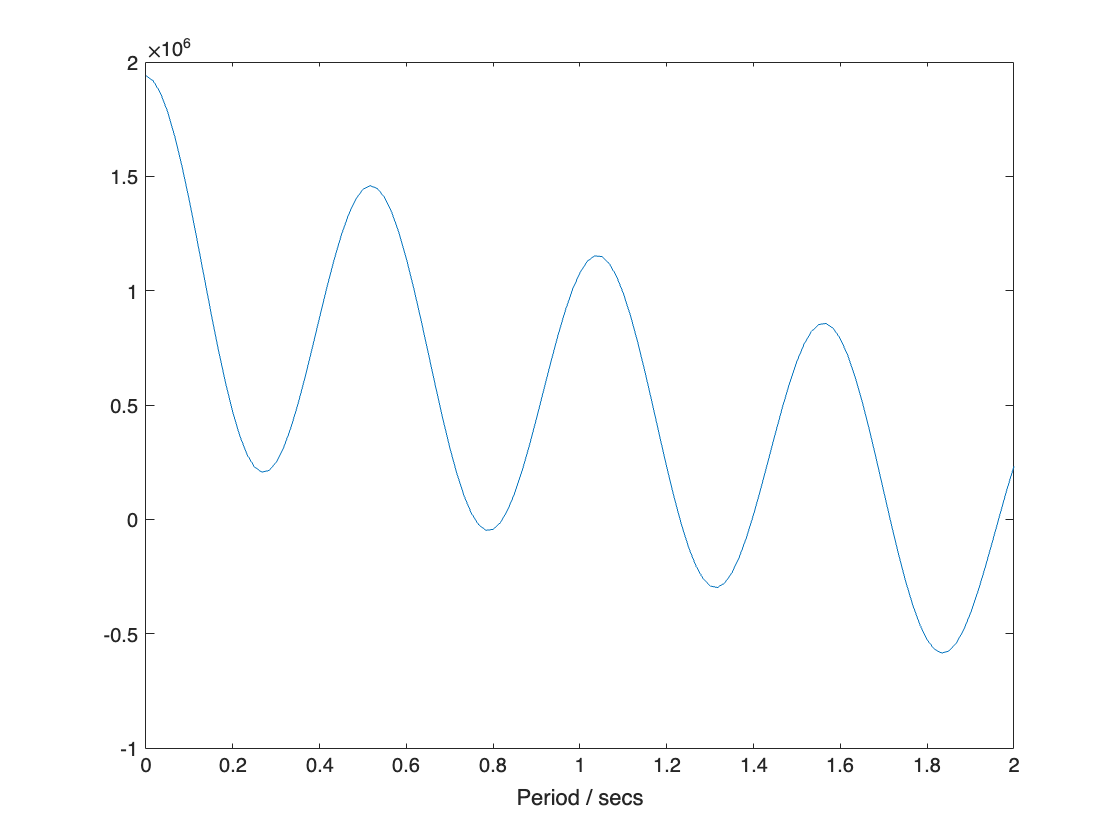


figure
plot(lag, ac(:,3)), xlabel('Period / secs')

**We can also get the enhanced autocorrelation function, which reduces the effect of some of the integer multiples of the basic period. Notice the peak at 0.51 secs**

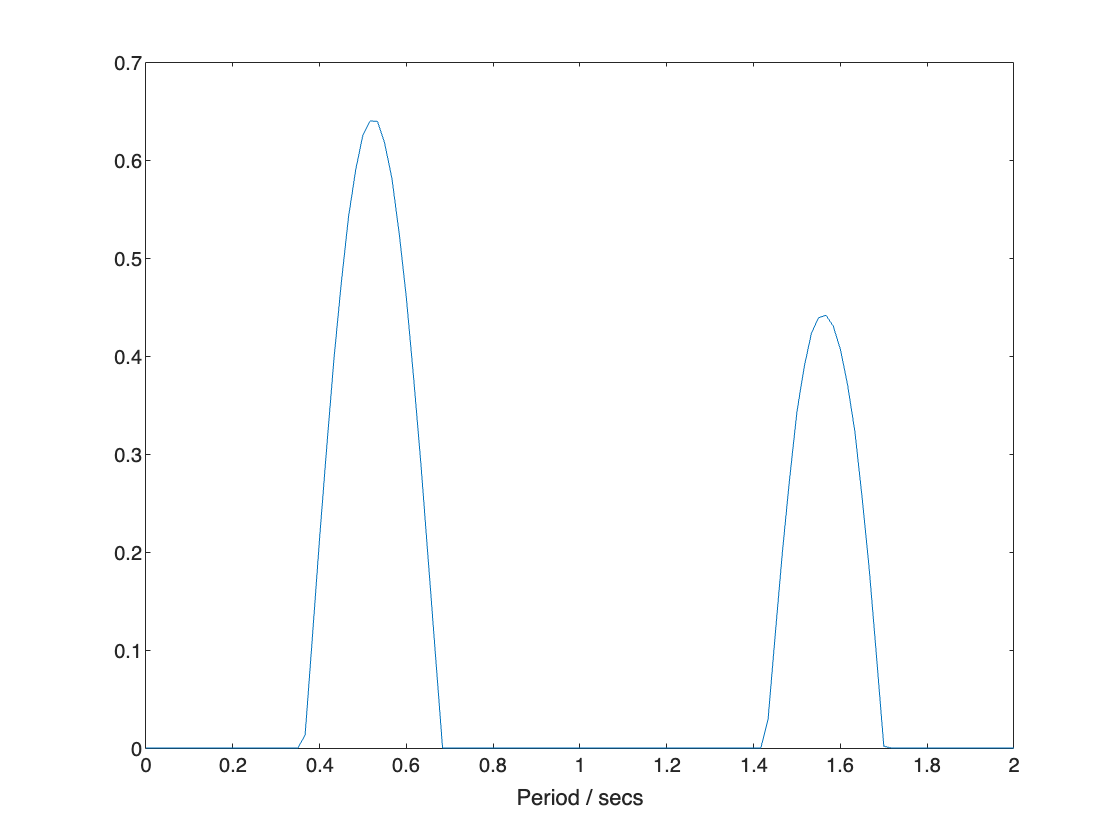


figure,
plot(lag, eac(:,3)), xlabel('Period / secs')

# **Interpersonal synchrony**

**This demo shows how to perform interpersonal synchrony and phase coupling analysis.**

**Let us first load joint representations from recordings of a dancing dyad:**

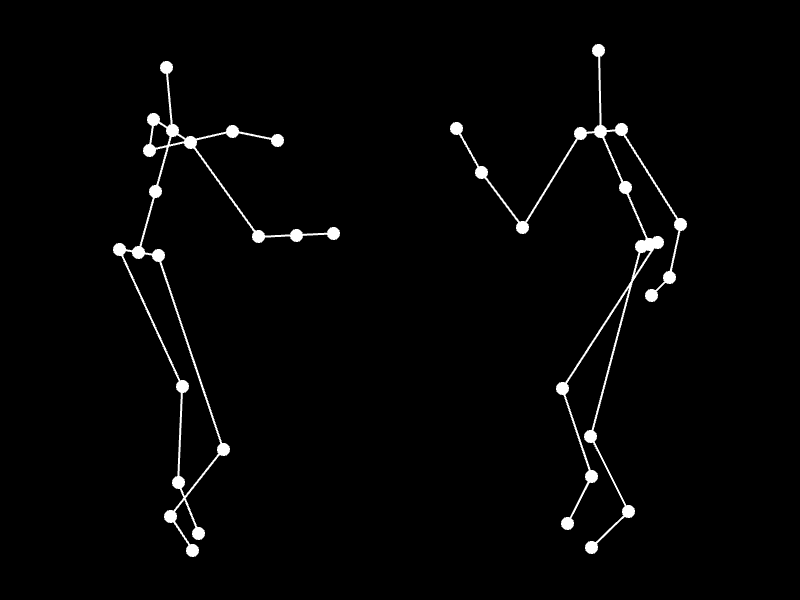

%cd ~/Documents/MCT_workshop % Adjust to your needs to navigate to the folder containing the files of this tutorial
clear all
load mcdemodata
load intdemo.mat
japar.az=90; % adjust the camera view
d12 = mcmerge(d1,d2,japar,japar); % merge for visualization
japar.conn = [japar.conn; max(japar.conn(:))+japar.conn]; % add connections for the second dancer
japar.fps = 15;
japar.videoformat = 'mpeg4';
japar.output = 'int_synchrony';
mcplotframe(d12,1,japar);

**Let's create an animation to have a look at their synchronized dance movements:**

mcanimate(d12,japar);

**We can visualize their generalized cross-wavelet transform (GXWT) magnitudes, which describe how synchronized the dancers are at different frequencies:**

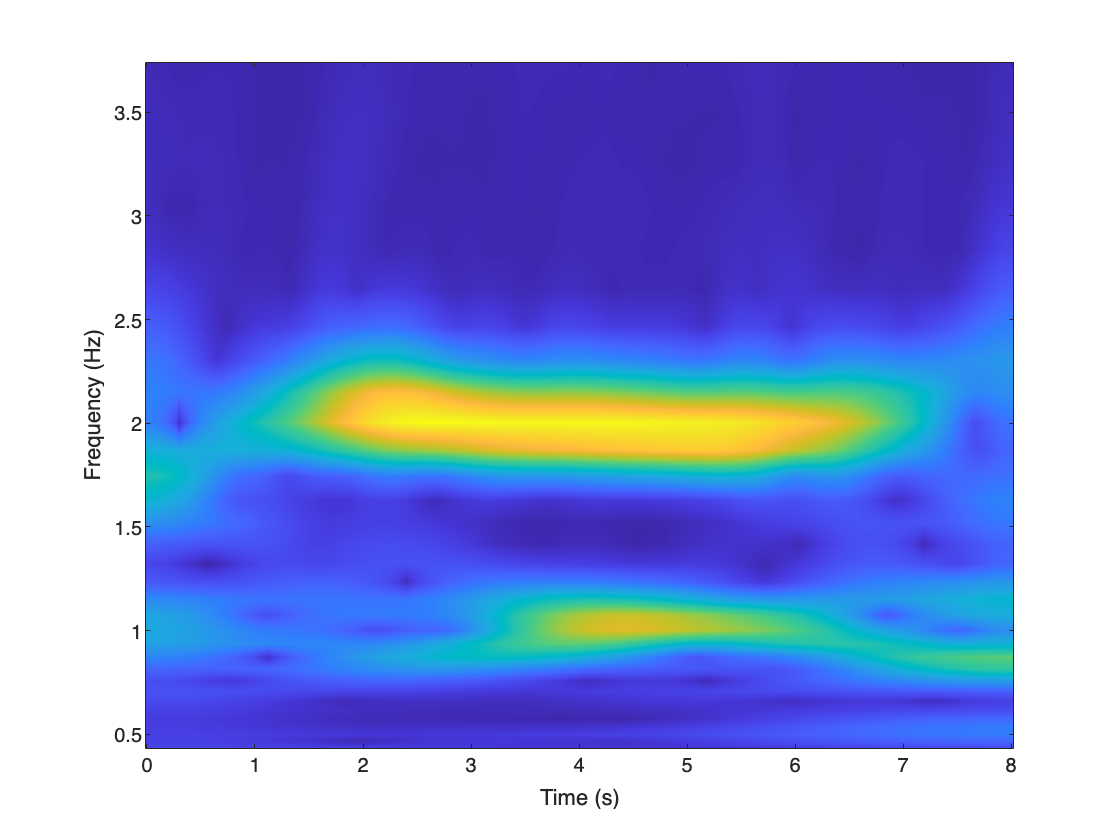

d1v = mctimeder(d1); % velocity yields clearer GXWT magnitudes
d2v = mctimeder(d2);
mcgxwt(d1v,d2v,maxf=4);

According to this plot, the dancers are mainly interacting at ~2 Hz (~120 BPM) and ~1 Hz.

**The music danced to has a tempo of 120 BPM. Let us visualize beat-relative GXWT magnitudes:**

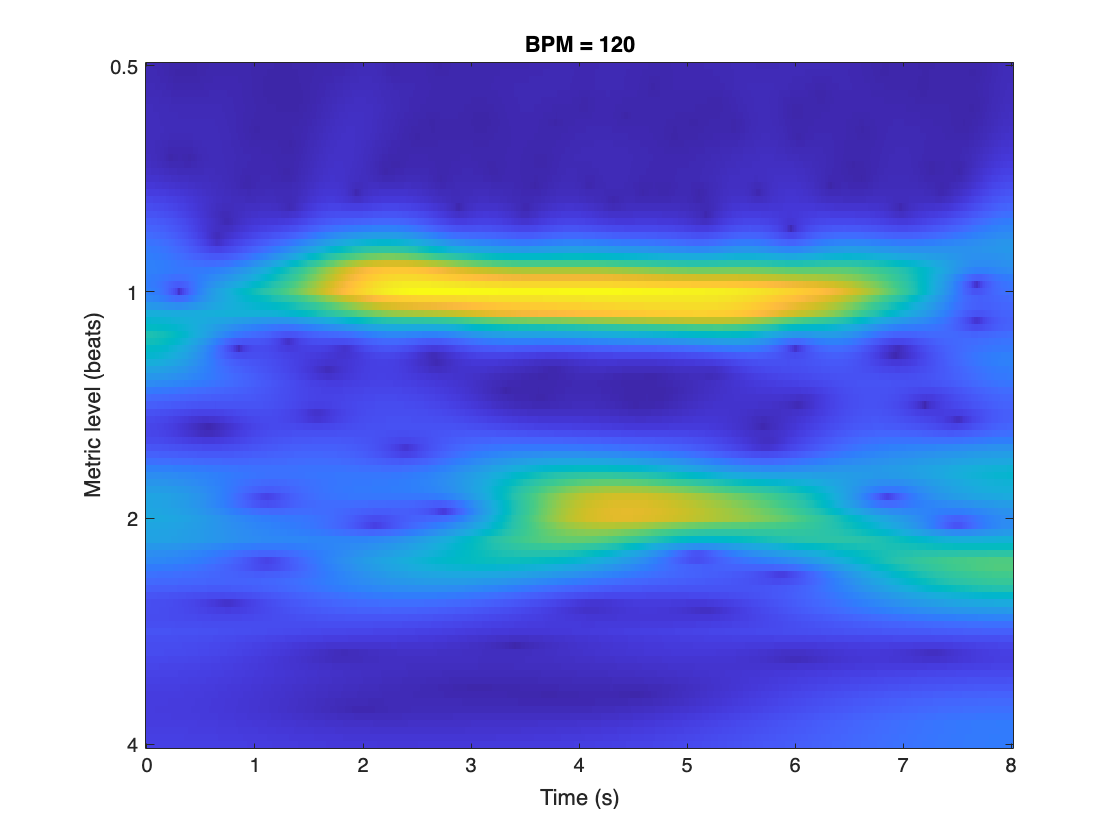


mcgxwt(d1v,d2v,BPM=120,freqBandsPerOctave=2^5,metricRange=[.5 4]);

**Let us use Hilbert transform to perform a phase analysis from vertical position data.**

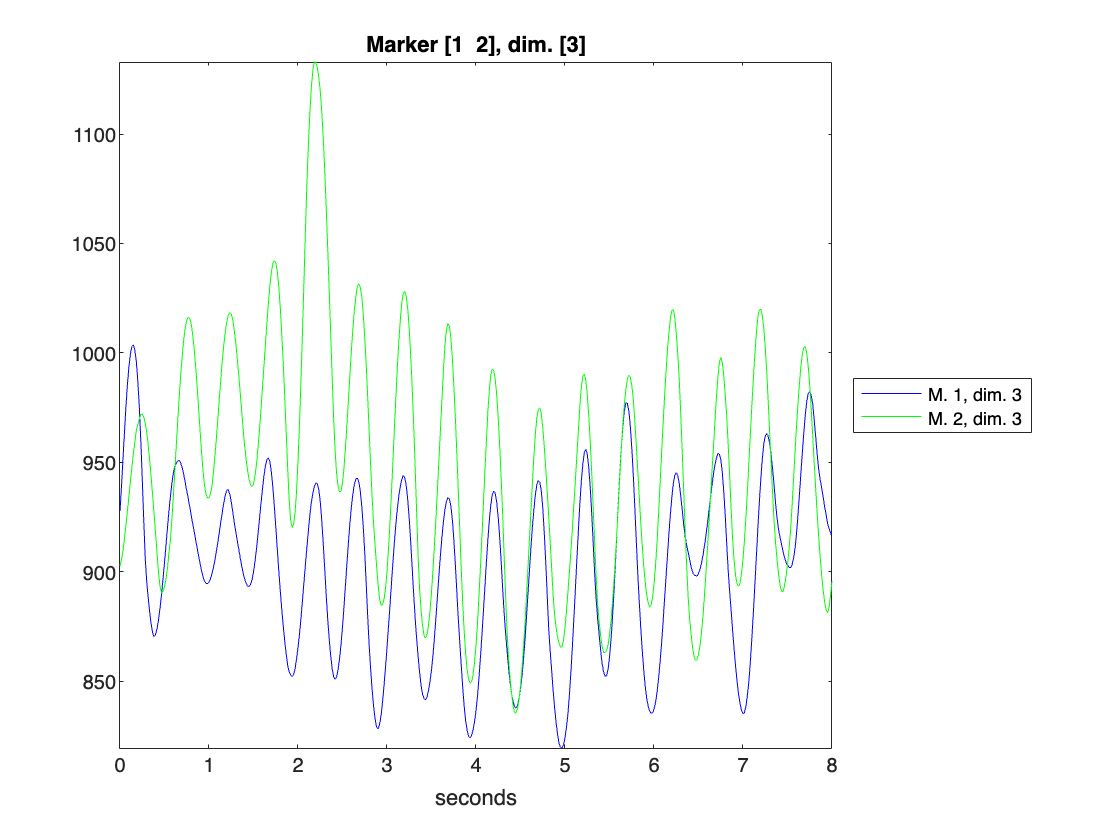

r1 = mcgetmarker(d1,1); % take root joint
r2 = mcgetmarker(d2,1); 
m=mcmerge(r1, r2);
mcplottimeseries(m,[1 2],'dim',3,'plotopt', 'comb'); %plot position data for reference

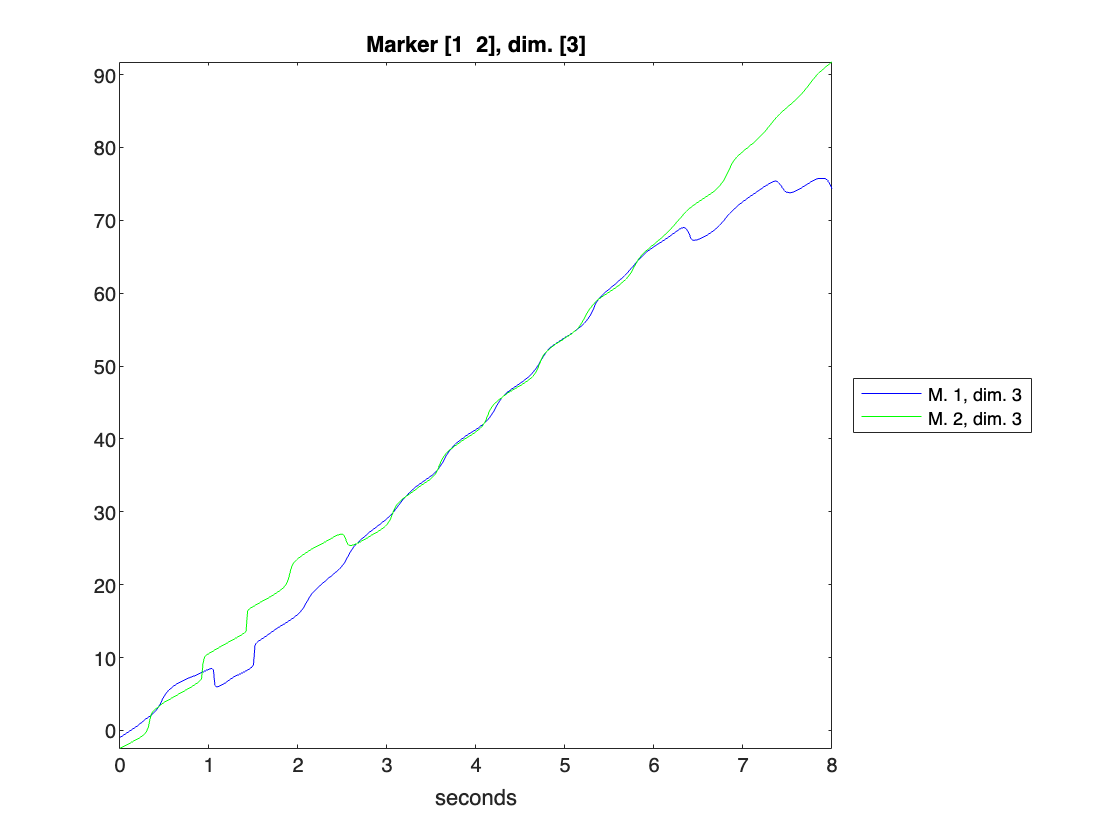

[~, ph1]=mchilbert(r1); %hilbert transform
[~, ph2]=mchilbert(r2); 
phh=mcmerge(ph1, ph2);
mcplottimeseries(phh,[1 2],'dim',3, 'plotopt', 'comb'); %plot unwrapped phase data (in radians)

**There are similiarities in the unwrapped phase data between 3s and 6s, suggesting high vertical phase coupling between the dancers.**